# Laboratorio - Analisis y simulacion de robot industrial 

## 1.Localizacion de ruta 

De acuerdo al grafico de la siguiente figura se crea la trayectoria a trozos en un plano XY que posteriormente sera rotado y transladado al espacio de trabajo del robot.

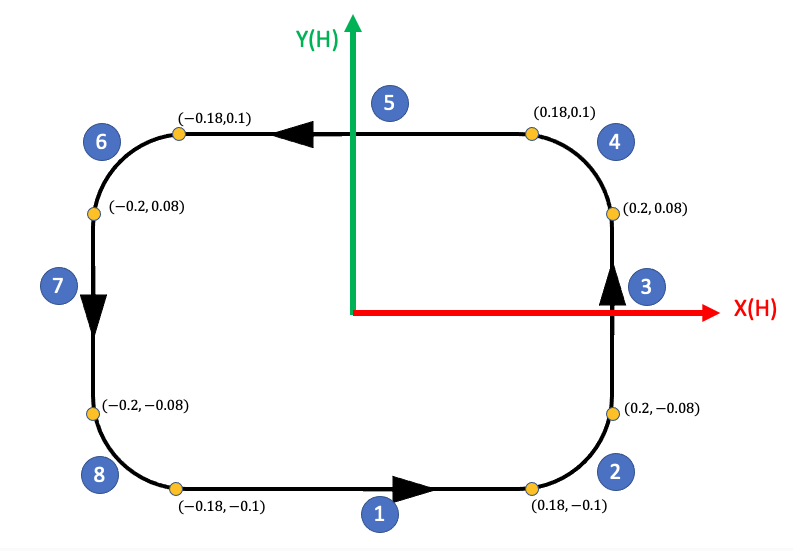

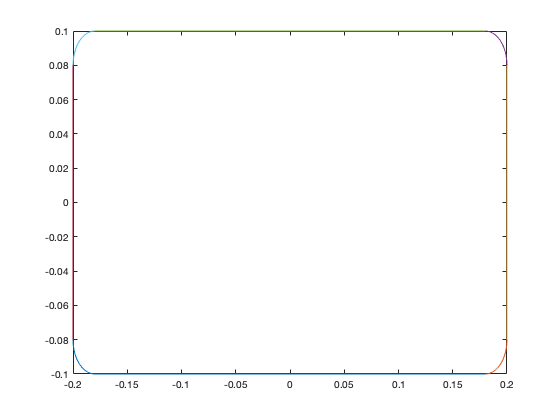

clc
clear
close all

a = 0.18; %distancia en x
b = 0.1;  %distancia en y
c = 0.08; %centro en y de los semicirculos
r = 0.02; %radio 

%%Ruta 1
x = -a:0.01:a;
len = size(x);
y = -b*ones(1,len(2));
z = zeros(1,len(2));
R1 = [x;y;z];
traye = R1;

figure()
plot(x,y);
hold on

%%Ruta 2
t = 3*pi/2:pi/20:2*pi;
x = 0.02*cos(t)+a;
y = 0.02*sin(t)-c;
len = size(x);
z = zeros(1,len(2));
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);
%%Ruta 3
y = -c:0.01:c;
len = size(y);
x = (a+r)*ones(1,len(2));
z = zeros(1,len(2));
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 4
t = 0:pi/20:pi/2;
x = 0.02*cos(t)+a;
y = 0.02*sin(t)+c;
len = size(x);
z = zeros(1,len(2));
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 5
x = -a:0.01:a;
len = size(x);
y = b*ones(1,len(2));
z = zeros(1,len(2));
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 6
t = pi/2:pi/20:pi;
x = 0.02*cos(t)-a;
y = 0.02*sin(t)+c;
len = size(x);
z = zeros(1,len(2));
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 7
y = -c:0.01:c;
len = size(y);
x = -(a+r)*ones(1,len(2));
z = zeros(1,len(2));
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 8
t = pi:pi/20:3*pi/2;
x = 0.02*cos(t)-a;
y = 0.02*sin(t)-c;
len = size(x);
z = zeros(1,len(2));
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%Matriz de Rotacion
R = [1/sqrt(2),0,-1/sqrt(2);
     0        ,1,0         ;
     1/sqrt(2),0, 1/sqrt(2)];
% Desplazamiento
x = 500;
y = 600;
z = 400;

%% Rotacion y dezplazamiento de la trayectoria

len = size(traye);
for i = 1:len(2)
    traye(1:3,i) = R*traye(1:3,i);
end

traye(1,:) = x + traye(1,:);
traye(2,:) = y + traye(2,:);
traye(3,:) = z + traye(3,:);

## 2.Caracteristicas y modelo del robot

- Imagen del robot. https://www.robots.com/robots/fanuc-lr-mate-200ib

http://geek.nmt.edu/~bruder/final_project_files/Fanuc%20LR%20Mate_200ib_200ib_3l.pdf

			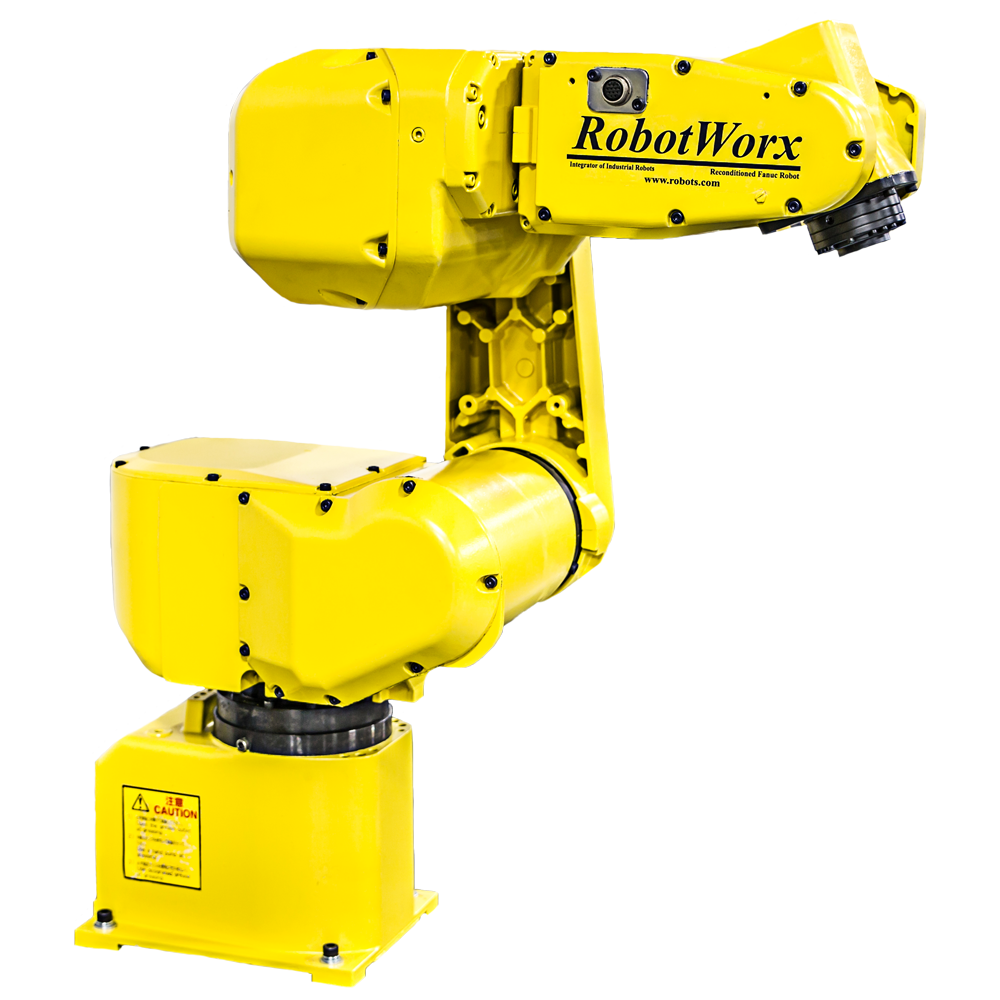		

2. Capacidad de carga = 5 kg.

3. Alcance vertical y horizontal. 

H-Reach: 7000 mm			

4. Repetibilidad. = **± 0.04mm**

5. Grafica(s) de espacio alcanzable.

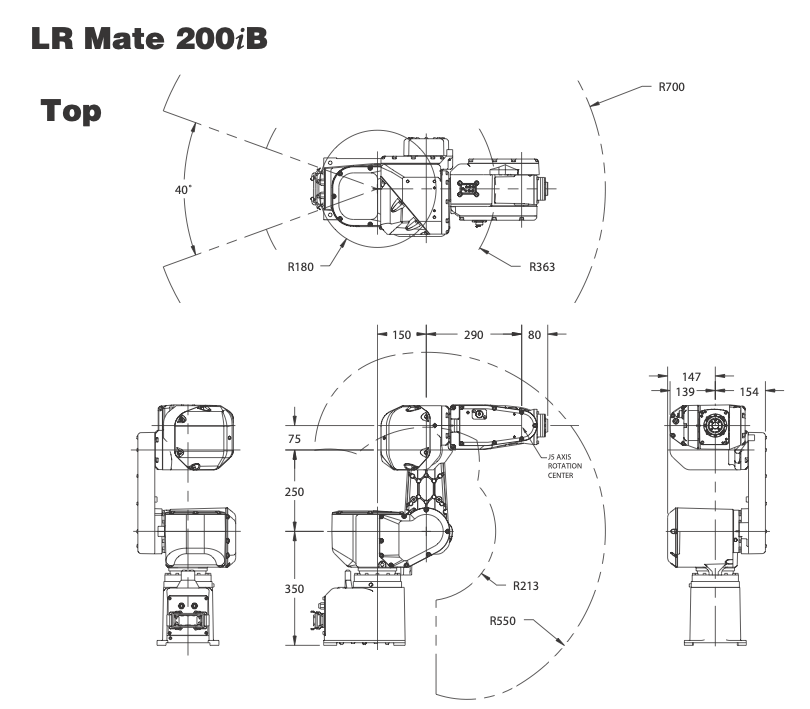

6. Tabla de parametros DH.

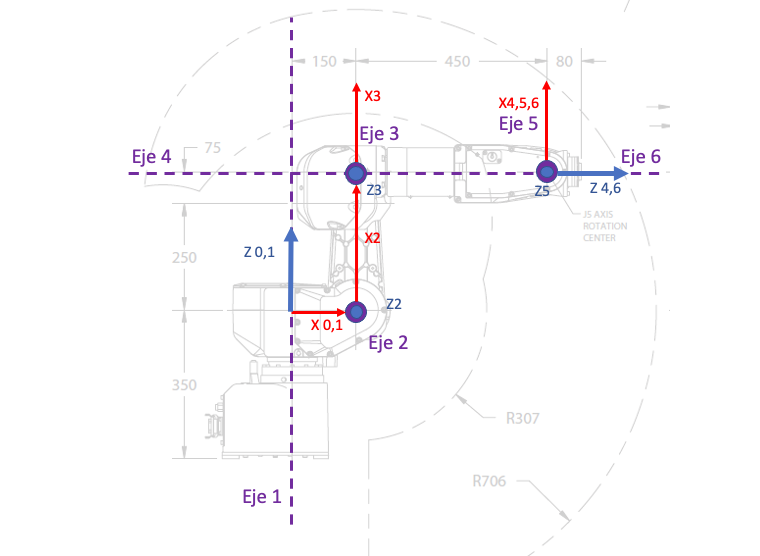

clc;clear;close all
l1 = 250; l2 = 150; l3 = 450;l4 = 80;
ws= [-70 80 -70 80 -20 90]/20;
plot_options = {'workspace',ws,'scale',0.5,'view',[-100 30], 'tilesize',2,  'ortho', 'lightpos',[2 2 10] };
L(1) = Link('revolute'  ,'alpha', 0,  'a',  0,     'd',     0,'offset',0,'qlim', [-8*pi/9 8*pi/9],   'modified');
L(2) = Link('revolute'  ,'alpha', pi/2,  'a',  l1, 'd',     0,'offset',pi/2, 'qlim',  [-7*pi/36 5*pi/6],   'modified');
L(3) = Link('revolute'  ,'alpha', 0,  'a',  l1, 'd',     0,'offset',0, 'qlim',  [-11*pi/18 103*pi/90],   'modified');
L(4) = Link('revolute'  ,'alpha',  pi/2,  'a',  0, 'd',   l3,'offset',  0, 'qlim',    [-19*pi/18 19*pi/18],   'modified');
L(5) = Link('revolute'  ,'alpha', -pi/2,  'a',  0, 'd',   0,'offset',  0, 'qlim',    [-2*pi/3 2*pi/3],   'modified');
L(6) = Link('revolute'  ,'alpha', pi/2,  'a',  0, 'd',   0,'offset',  0, 'qlim',    [-2*pi 2*pi],   'modified');

Robot = SerialLink(L,'name','Robot','plotopt',plot_options);


7. Que software utiliza el fabricante para diseño de celdas o programacion. 

- Capacidad de 

a = 1;